clearing commands

clc
clear all 
close all

input parameters: fc,ac, fm,am, be, pulses

Fc = 1000;
Ac = 1;
Fm = 350;
Am = 1;
be = 1;
no_per = 6;

msg sgnl generation: am sin(2 pi fm t)

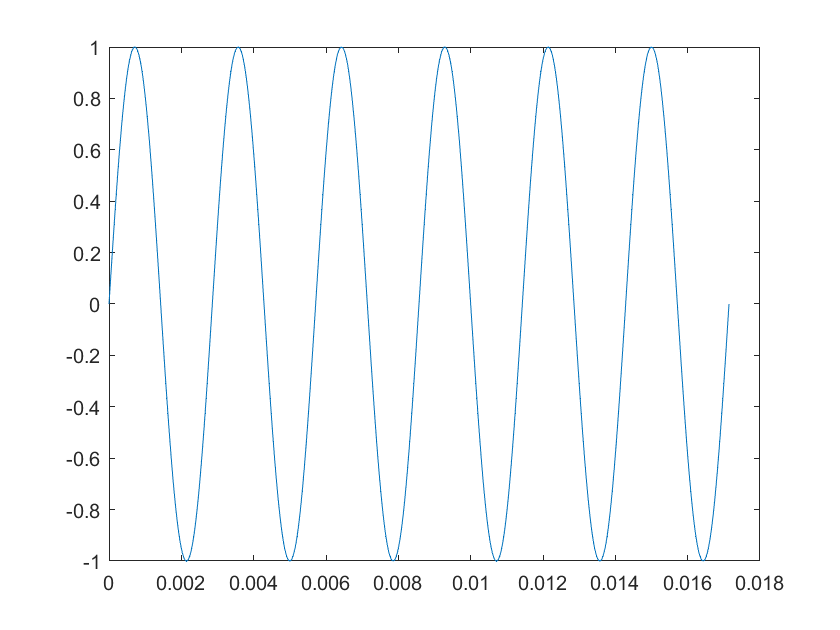

Tm = 1/Fm; % 1 sec
samples_per = 100; 
%Fs = samples_per* Fm;
Tsm = Tm/samples_per; % 0.1 sec

tm = 0: Tsm: no_per*Tm ;% 0 0.1 0.2 .... 1

msg_sgnl = Am * sin( 2* pi* Fm*tm);
plot(tm, msg_sgnl)

Carrier signal generation

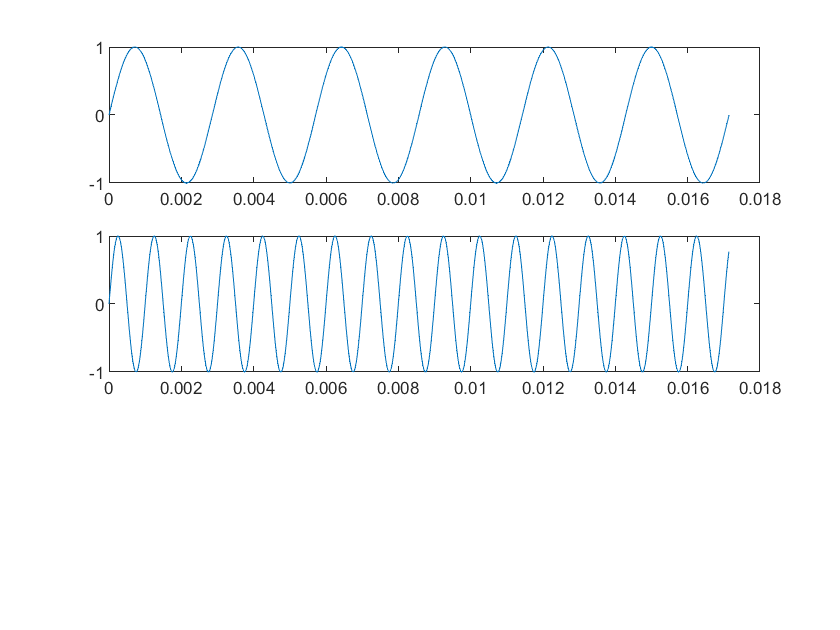

Tc = 1/Fc; % 1 sec
samples_per = 100; 
%Fs = samples_per* Fm;
Tsc = Tc/samples_per; % 0.1 sec

tc = 0: Tsc: no_per*Tm ;% 0 0.1 0.2 .... 1

car_sgnl = Ac * sin( 2* pi* Fc*tc);
subplot(3,1,1)
plot(tm, msg_sgnl)
subplot(3,1,2)
plot(tc, car_sgnl)

Generating FM Signal

FM_sgnl = Ac cos(2 pi Fc t + be sin(2 pi Fm t))

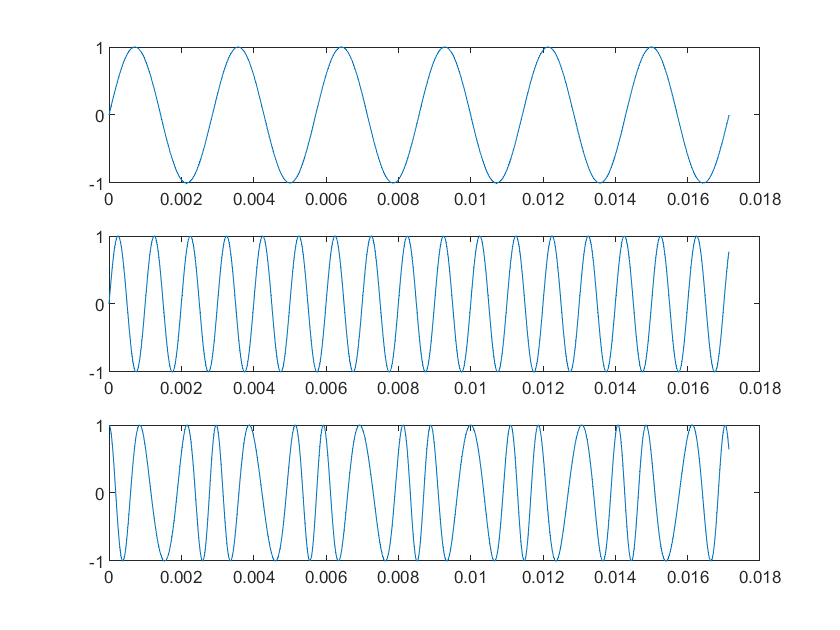

t = Tsc:Tsc:no_per*Tm;
fm_sgnl = Ac * cos(2*pi*Fc*t + be *sin(2*pi*Fm*t));
subplot(3,1,3)
plot(t, fm_sgnl)